data = [0, 0.02, 0.04, 0.06, 0.08, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 0.95, 1.0;
     0, 0.134, 0.23, 0.304, 0.365, 0.418, 0.579, 0.665, 0.729, 0.779, 0.825, 0.87, 0.915, 0.958, 0.979, 1];

x = data(1, :); 
y = data(2, :); 

% Plot equilibrium data
figure(1);
plot(x, y, 'ro', 'MarkerSize', 6, 'DisplayName', 'Data');
hold on;

% Fit the equilibrium curve
eqn = 'a*x/(1 + b*x + c*(x^2))';
initialGuess = [1, 1, 1]; % Initial parameters for the fit
f = fit(x', y', eqn, 'StartPoint', initialGuess);

disp('Fitted Parameters:');

Fitted Parameters:


disp(f);

     General model:
     f(x) = a*x/(1 + b*x + c*(x^2))
     Coefficients (with 95% confidence bounds):
       a =       7.967  (7.812, 8.122)
       b =       9.411  (9.122, 9.7)
       c =      -2.438  (-2.599, -2.278)


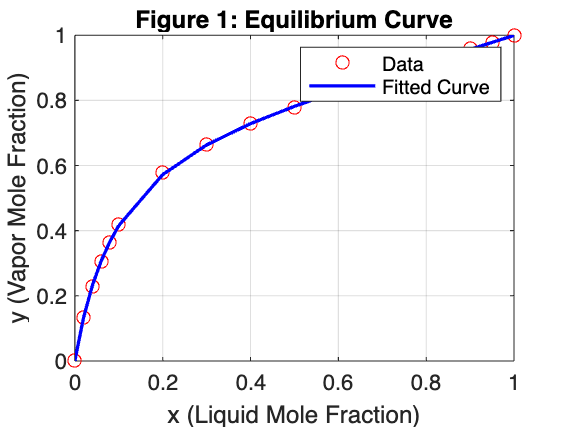

params = coeffvalues(f);
a = params(1);
b = params(2);
c = params(3);

fitted_y = feval(f, x); % Evaluate the fitted curve
plot(x, fitted_y, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Fitted Curve');
legend('show');
title('Figure 1: Equilibrium Curve');
xlabel('x (Liquid Mole Fraction)');
ylabel('y (Vapor Mole Fraction)');
grid on;
hold off;

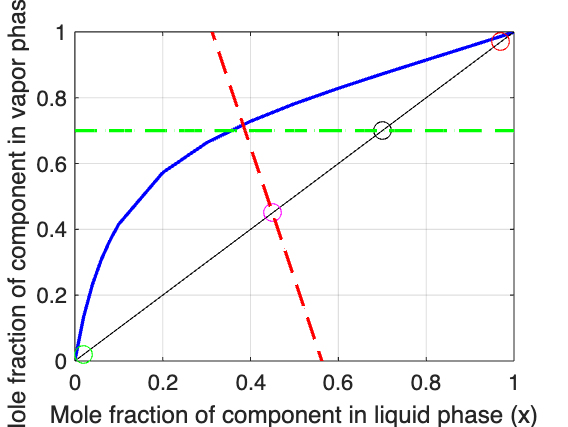


% Distillation parameters
xd = 0.97; % Distillate composition
xw = 0.02; % Bottoms composition
F = 500000; % Feed flowrate
S = 50; % Side stream flowrate
zf = 0.45; % Feed composition
xs = 0.7; % Side stream composition
syms D W

% Solve mass balance equations
fitted_y = feval(f, x); % Re-evaluate the fitted curve
figure(1);
plot(x, y, 'ro', 'MarkerSize', 6, 'DisplayName', 'Data');
hold on;
plot(x, fitted_y, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Fitted Curve');
legend('show');
title('Figure 1: Equilibrium Curve');
xlabel('x (Liquid Mole Fraction)');
ylabel('y (Vapor Mole Fraction)');
grid on;
hold off;

% Correct mass balance equations
eq_1 = F == D + W + S;
eq_2 = F*zf == D*xd + W*xw + S*xs;
solution = solve([eq_1, eq_2], [D, W]);
D = double(solution.D);
W = double(solution.W);

% Plot operating lines on Figure 2
figure(2);
plot(x, fitted_y, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Equilibrium Curve');
hold on;
plot([0 1], [0 1], '-k', 'LineWidth', 0.5, 'DisplayName', '45° Line');

% Plot key points
plot(xd, xd, 'ro', 'MarkerSize', 8, 'DisplayName', 'Distillate (D)');
plot(xw, xw, 'go', 'MarkerSize', 8, 'DisplayName', 'Bottoms (W)');
plot(xs, xs, 'ko', 'MarkerSize', 8, 'DisplayName', 'Side Stream (S)');
plot(zf, zf, 'mo', 'MarkerSize', 8, 'DisplayName', 'Feed (F)');

% Feed line
slope_feed = (zf - xw) / (xf - xw); % Check this calculation
intercept_feed = zf - slope_feed * zf; % Adjust slope or intercept if needed
feed_line = @(x) slope_feed * x + intercept_feed;
fplot(feed_line, [xw, xf], '--r', 'LineWidth', 1.5, 'DisplayName', 'Feed Line');

% Side-stream line
slope_side = (xs - xd) / (S - D); % Correct side-stream equation
side_line = @(x) slope_side * x + intercept_side;
fplot(side_line, [xd, xs], '--g', 'LineWidth', 1.5, 'DisplayName', 'Side Stream Line');

% Add legend and finalize plot
legend('show');
title('Figure 2: Operating Lines and Key Points');
xlabel('Mole Fraction (x)');
ylabel('Mole Fraction (y)');
grid on;
hold off;eq_1 = F == D + W + S;
eq_2 = F*zf == D*xd + W*xw + S*xs;
solution = solve([eq_1, eq_2], [D, W]);
D = double(solution.D);
W = double(solution.W);

% Plot the equilibrium curve and operating lines
figure(2);
plot(x, fitted_y, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Equilibrium Curve');
hold on;
plot([0 1], [0 1], '-k', 'linewidth', 0.5); % Plotting 45° line
hold on;

xlabel('Mole fraction of component in liquid phase (x)');
ylabel('Mole fraction of component in vapor phase (y)');
grid on;
set(gca, 'xlim', [0 1]);
set(gca, 'ylim', [0 1]);

% Mark key points
plot(xd, xd, 'ro', 'MarkerSize', 8, 'DisplayName', 'Distillate (D)');
plot(xw, xw, 'go', 'MarkerSize', 8, 'DisplayName', 'Bottoms (W)');
plot(xs, xs, 'ko', 'MarkerSize', 8, 'DisplayName', 'Side Stream (S)');
plot(zf, zf, 'mo', 'MarkerSize', 8, 'DisplayName', 'Feed (F)');


q = 0.8; % Liquid fraction of the feed
slope_feed = q / (q - 1);
intercept_feed = zf / (1 - q);
feed_line = @(x) slope_feed * x + intercept_feed;
fplot(feed_line, [0, 1], 'r--', 'LineWidth', 1.5, 'DisplayName', 'Feed Line');

% Side stream line
slope_side = (S * xs) / (D * xd); % Slope from mass balance
intercept_side = xs; % Passes through S(xs, xs)
side_stream_line = @(x) slope_side * x + intercept_side;
fplot(side_stream_line, [0, 1], 'g--', 'LineWidth', 1.5, 'DisplayName', 'Side Stream Line');


% Operating line for Section I
slope_op1 = L1 / V1;

Unrecognized function or variable 'L1'.

op_line1 = @(x) slope_op1 * x + (xd - slope_op1 * xd);
fplot(op_line1, [xw, xd], 'm-', 'LineWidth', 1.5, 'DisplayName', 'Operating Line Section I');

% Operating line for Section III
slope_op3 = L3 / V3;
op_line3 = @(x) slope_op3 * x + (xw - slope_op3 * xw);
fplot(op_line3, [xw, zf], 'c-', 'LineWidth', 1.5, 'DisplayName', 'Operating Line Section III');

legend('show');
xlabel('x (Liquid Mole Fraction)');
ylabel('y (Vapor Mole Fraction)');
title('Figure 2: McCabe-Thiele Diagram and Operating Lines');
grid on;

% McCabe-Thiele Construction
% Start from distillate composition
x_current = xd;
y_current = xd;
plot(x_current, y_current, 'r*', 'DisplayName', 'Tray Steps');
hold on;

while x_current > xw
    % Step horizontally to the operating line
    y_next = feval(op_line1, x_current);
    plot([x_current, x_current], [y_current, y_next], 'k-');
    % Step vertically to the equilibrium curve
    x_next = feval(f, y_next);
    plot([x_current, x_next], [y_next, y_next], 'k-');
    x_current = x_next;
    y_current = y_next;
end

hold off;